# ARI - Homework 3		

% initialize
clear all
close all
clc

% useful commands
help tf 

 tf  Construct transfer function or convert to transfer function.
 
   Construction:
     SYS = tf(NUM,DEN) creates a continuous-time transfer function SYS with
     numerator NUM and denominator DEN. SYS is an object of type tf when
     NUM,DEN are numeric arrays, of type GENSS when NUM,DEN depend on tunable
     parameters (see REALP and GENMAT), and of type USS when NUM,DEN are
     uncertain (requires Robust Control Toolbox).
 
     SYS = tf(NUM,DEN,TS) creates a discrete-time transfer function with
     sample time TS (set TS=-1 if the sample time is undetermined).
 
     S = tf('s') specifies the transfer function H(s) = s (Laplace variable).
     Z = tf('z',TS) specifies H(z) = z with sample time TS.
     You can then specify transfer functions directly as expressions in S
     or Z, for example,
        s = tf('s');  H = exp(-s)*(s+1)/(s^2+3*s+1)
 
     SYS = tf

help step

 step  Step response of dynamic systems.
 
    [Y,T] = step(SYS) computes the step response Y of the dynamic system SYS. 
    The time vector T is expressed in the time units of SYS and the time 
    step and final time are chosen automatically. For multi-input systems,
    independent step commands are applied to each input channel. If SYS has 
    NY outputs and NU inputs, Y is an array of size [LENGTH(T) NY NU] where 
    Y(:,:,j) contains the step response of the j-th input channel.
 
    For state-space models, 
       [Y,T,X] = step(SYS) 
    also returns the state trajectory X, an array of size [LENGTH(T) NX NU] 
    for a system with NX states and NU inputs.
 
    For identified models (see IDMODEL),
       [Y,T,X,YSD] = step(SYS) 
    also computes the standard deviation YSD of the response Y (YSD is empty 
    if SYS does not contain parameter covariance information).
 
    [Y,...] = step(SYS

s = tf('s');

% type 'help' followed by the command to learn about that specific function
% using the percent sign allows comments in MATLAB
% to compile/run your livescript hit "run" at the top of your screen

## Tasks 	

*Please answer the following in the spaces provided below, justify your conclustion:	*

#### Assignment 1 – Identification of the first-order system									

- Based on your birthday, generate a step response of your unique system. The generating file can be found in Moodle. The syntax in MATLAB is: 

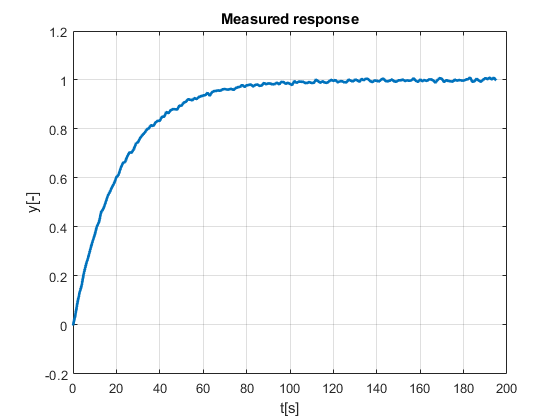

% insert your code here	
[y] = hw_3a_std(30, 05, 02);
s = tf('s');
num = length(y);
figure(1)
clear figure(1)
grid on

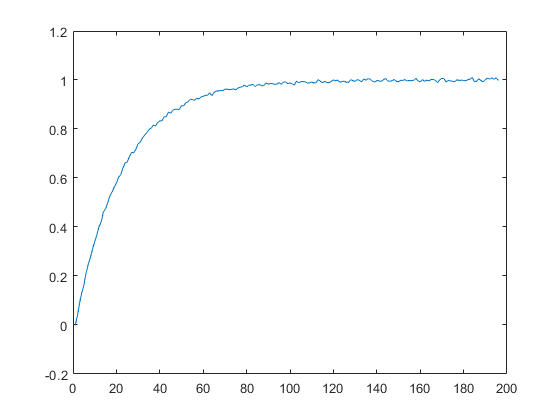

plot(y)

- Identify the first-order system, response of which you generated. The output is noisy. The transfer function is of the form:


$$F_1 \left(s\right)=\frac{k}{\textrm{Ts}+1}$$


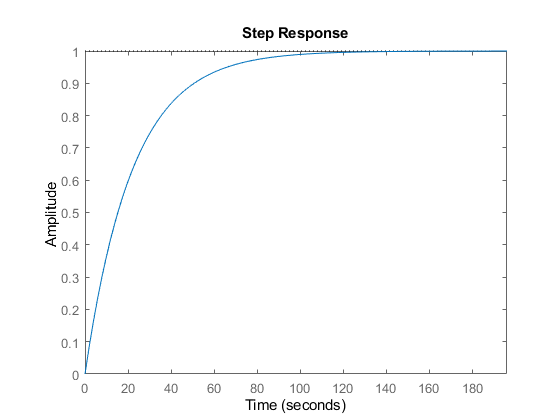

 % insert your code here	
 figure(2)
 clear figure(2)
 grid on
 step(1/(1+22*s), num)  % we make the value of T the value that corresponds to 0.63

- Compare the original step response and the step response of the system obtained by identification. Include the plot showing how well you identified the system.

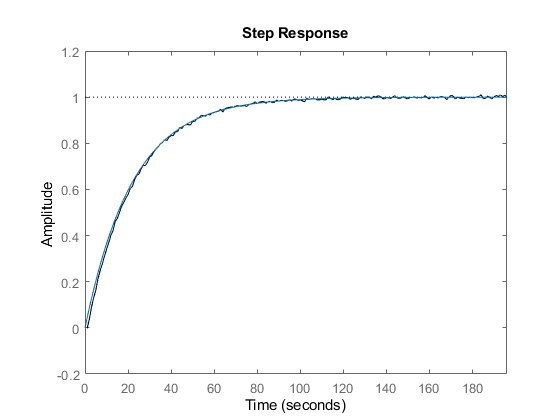

% insert your code here	
figure(3)
clear figure(3)
grid on
hold on
plot(y, 'k')
step(1/(1 + 22*s), num)
hold off

#### Assignment 2 – Identification of the second-order system									

- Using the function hw_3b_std, which can be also downloaded from Moodle, generate a step response of a second-order system. The syntax is identical to the function discussed above.

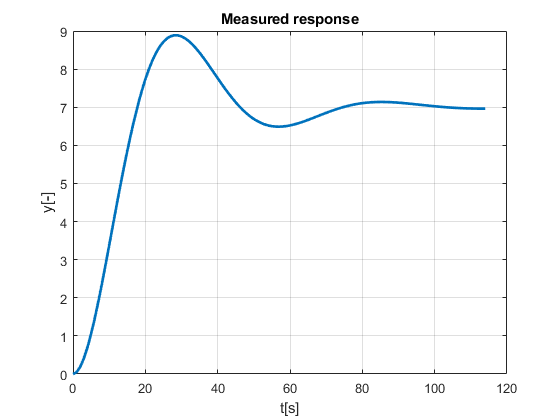

% insert your code here	
[y2] = hw_3b_std(30,05,02);

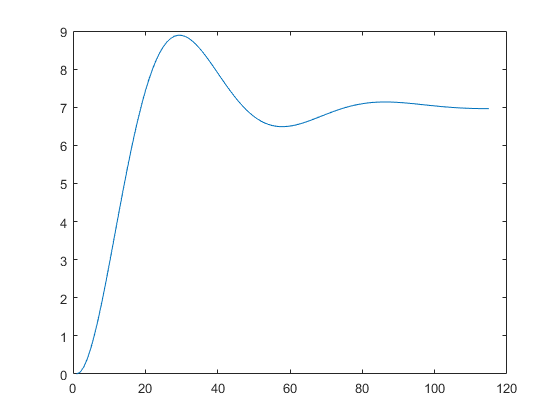

num2 = length(y2);
figure(4)
clear figure(4)
grid on
plot(y2)

- Identify the second-order system from the response. The structure of the transfer function is


$$F_2 \left(s\right)=k\frac{\omega_n^2 }{s^2 +2\xi \omega_n s+\omega_n^2 }$$


% insert your code here	
times = find((abs(diff(y2))<0.003)==true);

- Show the steady-state value, overshoot and settling time.

% insert your code here	
k = 7;
Ta = times(3)-times(1);
mu = log((y2(times(1))-7)/(y2(times(3))-7));


- Calculate the damping factor $\xi$, natural frequency $\omega_n$, and gain $k$, which you got by identification. Do not forget to include the approach for identification.

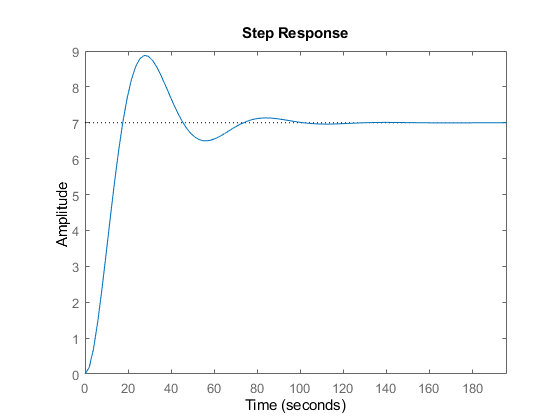

% insert your code here
epsilon = mu/sqrt(mu^2+4*pi^2);
omega = 2*pi/(Ta*sqrt(1-epsilon^2));
figure(5)
clear figure(5)
step(k*omega^2/(s^2 + 2*epsilon*omega*s + omega^2), num)

- Compare the responses of the original system and your identified system.

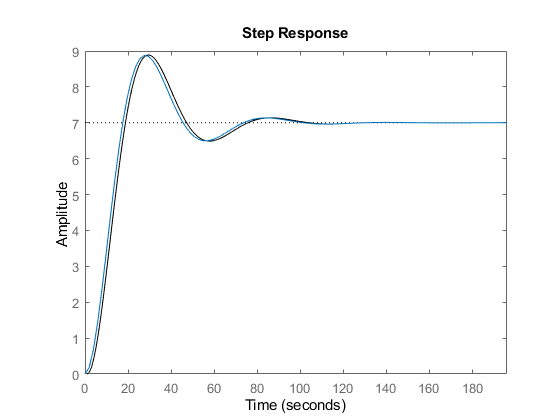

% insert your code here	
figure(6)
clear figure(6)
grid on
hold on
plot(y2, 'k')
step(k*omega^2/(s^2 + 2*epsilon*omega*s + omega^2), num)
hold off

function y = hw_3a_std(dd, mm, yy)
% Author: Kamil Dolinsky (last modified 27.6.2011)
%         Michael Sebek  (last modified 07-Feb-2012)


	[dd, mm, yy] = parseInput_3a(dd, mm, yy);
	[num,den] = get_parameters_3a(dd,mm,yy);
	
	y = step(num,den);
	y = get_noisy_output_3a(num,y);
	
	plot(0:length(y)-1,y,'LineWidth',2),xlabel('t[s]'),ylabel('y[-]'),title('Measured response'),grid on
end

function [dd, mm, yy] = parseInput_3a(dd, mm, yy)
	p = inputParser;
	p.addRequired('dd',@(x)isa(x,'numeric')&& size(x,1) == 1 && size(x,2) == 1 && x >= 1 && x <= 31 && mod(x,1) == 0);
	p.addRequired('mm',@(x)isa(x,'numeric')&& size(x,1) == 1 && size(x,2) == 1 && x >= 1 && x <= 12 && mod(x,1) == 0);
	p.addRequired('yy',@(x)isa(x,'numeric')&& size(x,1) == 1 && size(x,2) == 1 && x >= 0 && x <= 99 && mod(x,1) == 0);

	p.parse(dd, mm, yy);

	dd = p.Results.dd;
	mm = p.Results.mm;
	yy = p.Results.yy;
end

function dob = get_dob_3a(dd,mm)

	month = [31 28 31 30 31 30 31 31 30 31 30 31];

	if mm > 1
		dob = sum(month(1:mm-1)) + dd;
	else
		dob = dd;
	end
end

function [num, den] = get_parameters_3a(dd,mm,yy)
	dob = get_dob_3a(dd,mm);
	
	k = mod(mm*5+dd*3+yy*2,7) + 1;
	T = mod(dob + mod(dd,5) + 1,7) + 1;
	
	num = k;
	den = [T 1];
end

function y_1 = get_noisy_output_3a(k,y_1)
	randn('state', 0);
	noise_1 = randn(length(y_1),1);
	y_1 = y_1+noise_1*0.005*k;
end

function y = hw_3b_std(dd, mm, yy)
% Author: Kamil Dolinsky (last modified 27.6.2011)
%         Michael Sebek  (last modified 07-Feb-2012)

	[dd, mm, yy] = parseInput_3b(dd, mm, yy);
	[num,den] = get_parameters_3b(dd,mm,yy);
	
	y = step(num,den);
	
	plot(0:length(y)-1,y,'LineWidth',2),xlabel('t[s]'),ylabel('y[-]'),title('Measured response'),grid on
end

function [dd, mm, yy] = parseInput_3b(dd, mm, yy)
	p = inputParser;
	p.addRequired('dd',@(x)isa(x,'numeric')&& size(x,1) == 1 && size(x,2) == 1 && x >= 1 && x <= 31 && mod(x,1) == 0);
	p.addRequired('mm',@(x)isa(x,'numeric')&& size(x,1) == 1 && size(x,2) == 1 && x >= 1 && x <= 12 && mod(x,1) == 0);
	p.addRequired('yy',@(x)isa(x,'numeric')&& size(x,1) == 1 && size(x,2) == 1 && x >= 0 && x <= 99 && mod(x,1) == 0);

	p.parse(dd, mm, yy);

	dd = p.Results.dd;
	mm = p.Results.mm;
	yy = p.Results.yy;
end

function dob = get_dob_3b(dd,mm)

	month = [31 28 31 30 31 30 31 31 30 31 30 31];

	if mm > 1
		dob = sum(month(1:mm-1)) + dd;
	else
		dob = dd;
	end
end

function [num,den] = get_parameters_3b(dd,mm,yy)
	dob = get_dob_3b(dd,mm);
	
	alpha = -(mod(dob+mm,9) + mod(dd,4) + 1)/(mod(dob+5,8) + 1);
	omega = mod(dob*3+mm,13) + mod(mm*5+dd*3+yy*2,13) + 1;
	k_2 = mod(mm*2+dd*6+yy+dob,7) + 1;
	
	den = poly([alpha-i*omega alpha+i*omega]);
	num = den(1,3)*k_2;
end
